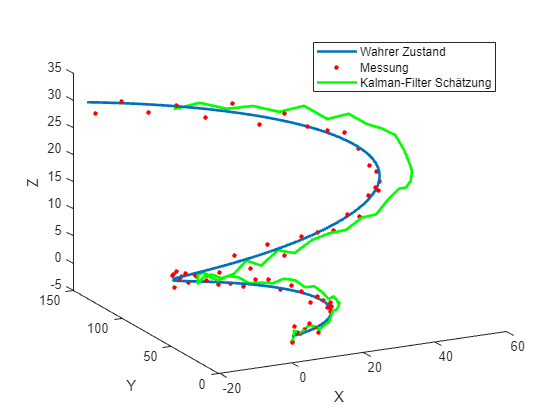

% Gegebenes Beispiel
R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;

R_measured = extract_every_third_column(R);
for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end

% Kalman-Filter Parameter
dt = 0.5;                % Abtastzeit
A_kalman = [1 dt dt^2/2; 0 1 dt; 0 0 1];       % Zustandsübergangsmatrix
B_kalman = [dt^3/6; dt^2/2; dt];      % Steuerungsmatrix (Beschleunigung)
C_kalman = eye(3);             % Messmatrix (direkte Messung von X, Y, Z)
Q_kalman = diag([0.8, 0.8, 0.8]);   % Prozessrauschkovarianz
R_kalman = diag([0.3, 0.5, 0.5]);                 % Messrauschkovarianz

% Initialisierung
x_kalman = zeros(3, length(R_measured));
P_kalman = zeros(3, 3, length(R_measured));

% Schätzung mit Kalman-Filter
for i = 1:length(R_measured)
    % Vorhersage
    if i == 1
        x_pred = [0; 0; 0];
        P_pred = eye(3);
    else
        x_pred = A_kalman * x_kalman(:, i-1) + B_kalman .* A(:, i-1);
        P_pred = A_kalman * P_kalman(:, :, i-1) * A_kalman' + Q_kalman;
    end
    
    % Korrektur
    K = P_pred * C_kalman' / (C_kalman * P_pred * C_kalman' + R_kalman);
    x_kalman(:, i) = x_pred + K * (R_measured(:, i) - C_kalman * x_pred);
    P_kalman(:, :, i) = (eye(3) - K * C_kalman) * P_pred;
end

% Ergebnisse anzeigen
figure;
hold on;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'r.', 'MarkerSize', 10);
plot3(x_kalman(1,:), x_kalman(2,:), x_kalman(3,:), 'g-', 'LineWidth', 2);
legend('Wahrer Zustand', 'Messung', 'Kalman-Filter Schätzung');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

% get distance values from the radar to the helicopter

dist_3dmatrix_radar1 = []; % Leere Matrix für dist_radar1
dist_3dmatrix_radar2 = []; % Leere Matrix für dist_radar2

for i = 1:length(R)
    dist3d_radar1 = [R(1,i)-pos_radar1(1), R(2,i)-pos_radar1(2), R(3,i)-pos_radar1(3)];
    dist3d_radar2 = [R(1,i)-pos_radar2(1), R(2,i)-pos_radar2(2), R(3,i)-pos_radar2(3)];
    
    dist_3dmatrix_radar1 = [dist_3dmatrix_radar1; dist3d_radar1]; % Vektor zu dist_matrix_radar1 hinzufügen
    dist_3dmatrix_radar2 = [dist_3dmatrix_radar2; dist3d_radar2]; % Vektor zu dist_matrix_radar2 hinzufügen
end

dist_matrix_radar1
dist_matrix_radar2

alpha_xy_radar1 = [];
alpha_xy_radar2 = [];

alpha_xz_radar1 = [];
alpha_xz_radar2 = [];

for i = 1:length(R_transposed)
    %%% Berechnung der Winkel in 
    % Berechnung des Winkels in Bogenmaß (Radiant) zwischen x-y-Ebene und Vektor von Radar 1 zum Punkt
    alpha_xy_rad1 = atan2(R_transposed(i,2)-pos_radar1(2), R_transposed(i,1)-pos_radar1(1));
    % Berechnung des Winkels in Bogenmaß (Radiant) zwischen x-y-Ebene und Vektor von Radar 2 zum Punkt
    alpha_xy_rad2 = atan2(R_transposed(i,1)-pos_radar2(1), R_transposed(i,2)-pos_radar2(2));
    
    % Umrechnung des Winkels in Grad
    alpha_xy_deg_radar1 = rad2deg(alpha_xy_rad1);
    alpha_xy_deg_radar2 = rad2deg(alpha_xy_rad2);
    
    alpha_xy_radar1 = [alpha_xy_radar1; alpha_xy_deg_radar1]; % Fügt den Winkel alpha_xy_deg_radar1 zu alpha_xy_radar1 hinzu
    alpha_xy_radar2 = [alpha_xy_radar2; alpha_xy_deg_radar2]; % Fügt den Winkel alpha_xy_deg_radar2 zu alpha_xy_radar2 hinzu

    
    % Berechnung des Winkels in Bogenmaß (Radiant) zwischen x-z-Ebene und Vektor von Radar 1 zum Punkt
    alpha_xz_rad1 = atan2(R_transposed(i,3)-pos_radar1(3), R_transposed(i,2)-pos_radar1(2));
    % Berechnung des Winkels in Bogenmaß (Radiant) zwischen x-z-Ebene und Vektor von Radar 2 zum Punkt
    alpha_xz_rad2 = atan2(R_transposed(i,3)-pos_radar2(3), R_transposed(i,2)-pos_radar2(2));
    
    % Umrechnung des Winkels in Grad
    alpha_xz_deg_radar1 = rad2deg(alpha_xz_rad1);
    alpha_xz_deg_radar2 = rad2deg(alpha_xz_rad2);
    
    alpha_xz_radar1 = [alpha_xz_radar1; alpha_xz_deg_radar1]; % Fügt den Winkel alpha_xz_deg_radar1 zu alpha_xz_radar1 hinzu
    alpha_xz_radar2 = [alpha_xz_radar2; alpha_xz_deg_radar2]; % Fügt den Winkel alpha_xz_deg_radar2 zu alpha_xz_radar2 hinzu

    
    
end


alpha_xy_radar1  % Gibt die Winkel alpha_xy_radar1 aus
alpha_xy_radar2  % Gibt die Winkel alpha_xy_radar2 aus

alpha_xz_radar1  % Gibt die Winkel alpha_xz_radar1 aus
alpha_xz_radar2  % Gibt die Winkel alpha_xz_radar2 aus

alpha_vertikal_radar1 = [];  % Leerer Vektor für die vertikalen Winkel von Radar 1
alpha_vertikal_radar2 = [];  % Leerer Vektor für die vertikalen Winkel von Radar 2

alpha_horizontal_radar1 = [];  % Leerer Vektor für die horizontalen Winkel von Radar 1
alpha_horizontal_radar2 = [];  % Leerer Vektor für die horizontalen Winkel von Radar 2

for i = 1:length(R_transposed)
    
    % Berechnung des Winkels nach oben (vertikal) von Radar 1
    delta_z = R_transposed(i,3) - pos_radar1(3);
    delta_y = R_transposed(i,2) - pos_radar1(2);
    alpha_vertikal_radar1 = [alpha_vertikal_radar1; rad2deg(atan(delta_z/delta_y))];  % Fügt den Winkel zu alpha_vertikal_radar1 hinzu
    
    % Berechnung des Winkels nach oben (vertikal) von Radar 2
    delta_z = R_transposed(i,3) - pos_radar2(3);
    delta_x = R_transposed(i,1) - pos_radar2(1);
    alpha_vertikal_radar2 = [alpha_vertikal_radar2; rad2deg(atan(delta_z/delta_x))];  % Fügt den Winkel zu alpha_vertikal_radar2 hinzu
    
    
    % Berechnung des Winkels nach rechts und links (horizontal) von Radar 1
    delta_x = R_transposed(i,1) - pos_radar1(1);
    delta_y = R_transposed(i,2) - pos_radar1(2);
    alpha_horizontal_radar1 = [alpha_horizontal_radar1; rad2deg(atan(delta_x/delta_y))];  % Fügt den Winkel zu alpha_horizontal_radar1 hinzu
    
    % Berechnung des Winkels nach rechts und links (horizontal) von Radar 2
    delta_y = R_transposed(i,2) - pos_radar2(2);
    delta_x = R_transposed(i,1) - pos_radar2(1);
    alpha_horizontal_radar2 = [alpha_horizontal_radar2; rad2deg(atan(delta_y/delta_x))];  % Fügt den Winkel zu alpha_horizontal_radar2 hinzu   
end

alpha_vertikal_radar1  % Gibt die vertikalen Winkel von Radar 1 aus
alpha_vertikal_radar2  % Gibt die vertikalen Winkel von Radar 2 aus

alpha_horizontal_radar1  % Gibt die horizontalen Winkel von Radar 1 aus
alpha_horizontal_radar2  % Gibt die horizontalen Winkel von Radar 2 aus

function new_array = extract_every_third_column(R)
    new_array = R(:, 1:3:end);
end